# Demo 4 - Clustering Functions

## Load example data

cdgea; % set working directory
% load('example_data/example10xdata2.mat','X','genelist');
[X,genelistx]=sc_readfile('example_data/GSM3204304_P_P_Expr.csv');

Reading example_data/GSM3204304_P_P_Expr.csv ...... done.


[Y,genelisty]=sc_readfile('example_data/GSM3204305_P_N_Expr.csv');

Reading example_data/GSM3204305_P_N_Expr.csv ...... done.


[X,genelistx]=sc_selectg(X,genelistx,3,1);
[Y,genelisty]=sc_selectg(Y,genelisty,3,1);

## Intersection of common genes in X, Y and Z

[genelist]=intersect(genelistx,genelisty,'stable');
% Remove genes encoded in the mitochondrial genome
i=startsWith(genelist,'MT-');
genelist(i)=[];
[~,i1]=ismember(genelist,genelistx);
[~,i2]=ismember(genelist,genelisty);
X=X(i1,:); genelistx=genelist;
Y=Y(i2,:); genelisty=genelist;

## Label cells

cellidx=[1*ones(size(X,2),1); 2*ones(size(Y,2),1)];

## Cluster cells using SIMLR

C = sc_cluster_x([X Y], 5, 'type', 'simlr');

Using 2000 HVGs.
NOTE: Genes with dropout rate > 0.95 are excluded.



% [C,s] = run.ml_SIMLR(X,[]);  % auto-determine the number of clusters.

## Plot the clustering result

s = sc_tsne([X Y], 2, true, false);   % s=sc_tsne(X,ndim,donorm,dolog1p);

Library-size normalization...done.


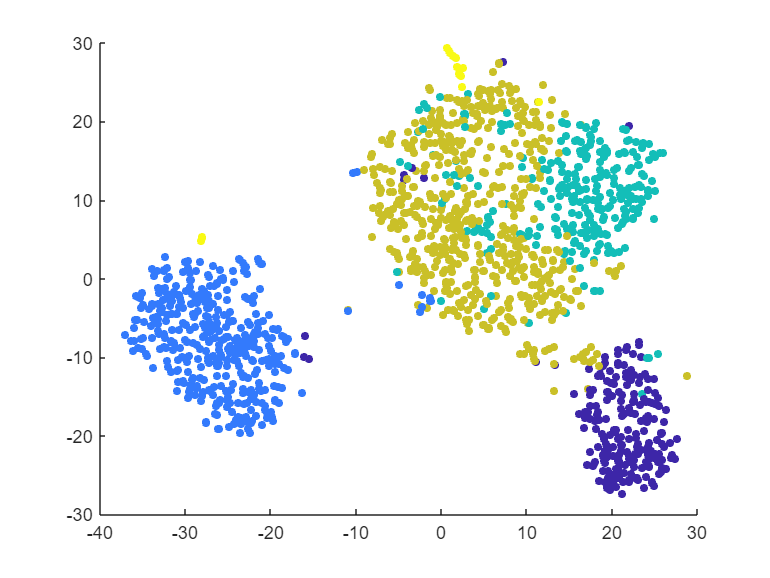

figure;
scatter(s(:,1), s(:,2), 20, C, 'filled')

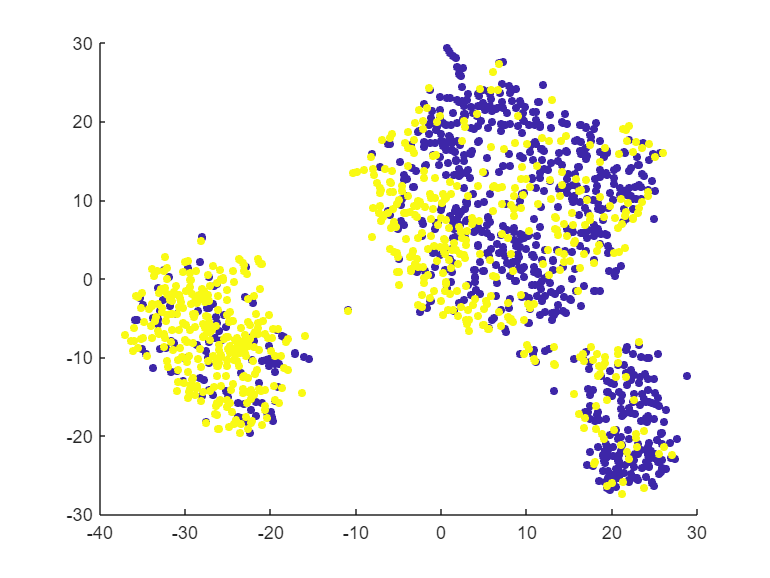


figure;
scatter(s(:,1), s(:,2), 20, cellidx, 'filled')

## Using SC3 example data yan.csv

[X,genelist] = sc_readtsvfile('example_data/yan.csv');

Reading example_data/yan.csv ...... done.


t = readtable('example_data/yan_celltype.txt');
celltypelist = string(t.cell_type1);
rng(235); showlegend = true;

s = sc_tsne(X, 2);

Library-size normalization...done.
Log(x+1) transformation...done.


c1 = run.ml_SC3(X, 6);

Processing Euclidean distance matrix... 1/3
Calculating cluster array: 100%    [..........]done
Processing Spearman distance matrix... 2/3
Calculating cluster array: 100%    [..........]done
Processing Pearson distance matrix... 3/3
Calculating cluster array: 100%    [..........]done
CLUSTER ENSEMBLES using CSPA
wgraph: writing graph0
 
D:\GitHub\scGEAToolbox\+run\external\mt_SC3\ClusterPack>pmetis graph0 6  
********************************************************************** 
  METIS 3.0   Copyright 1997, Regents of the University of Minnesota 
 
Graph Information --------------------------------------------------- 
  Name: graph0, #Vertices: 90, #Edges: 1111, #Parts: 6 
 
Recursive Partitioning... ------------------------------------------- 
  6-way Edge-Cut: 17536226, Balance:  1.20 
 
Timing Information -------------------------------------------------- 
  I/O:          		   0.001 
  Partitioning: 		   0.001   (PMETIS time) 
  Total:        		   0.002 
**************************

c2 = run.ml_SIMLR(X, 6);
c3 = run.ml_SoptSC(X, 'k', 6);

Iter  Err
1, 6.867832
2, 5.876795
3, 5.042887
4, 4.362326
5, 3.807127
6, 3.351183
7, 2.973775
8, 2.658954
9, 0.711817
10, 0.112101
11, 0.103572
12, 0.098797
13, 0.093055
14, 0.087015
15, 0.081145
16, 0.075632
17, 0.070527
18, 0.062194
19, 0.050105
20, 0.034833
21, 0.017597
22, 0.019880



% Result of SC3/R pacakge
load example_data/sc3_results.txt
c0 = sc3_results;

## Compare clustering results between SC3/R vs SC3, SIMILR and SoptSC

Cal_NMI(c0,c1)

ans = 0.9205

Cal_NMI(c0,c2)

ans = 0.8200

Cal_NMI(c0,c3)

ans = 0.5464

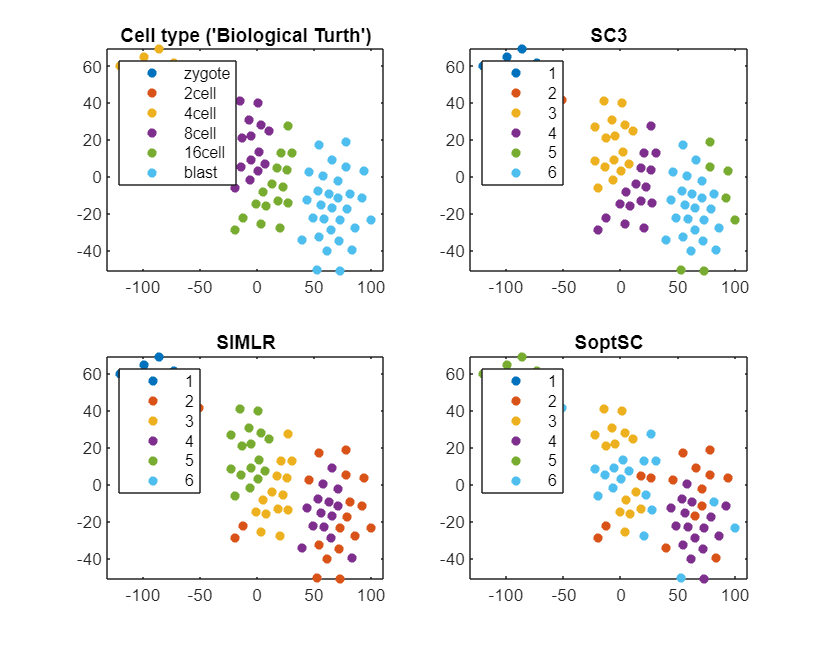



fh=figure; 
subplot(2,2,1)
gscatter(s(:,1),s(:,2),celltypelist)
if showlegend, legend('Location','northwest'); else, legend off; end
title('Cell type (''Biological Turth'')')

subplot(2,2,2)
gscatter(s(:,1),s(:,2),c1)
if showlegend, legend('Location','northwest'); else, legend off; end
title('SC3')

subplot(2,2,3)
gscatter(s(:,1),s(:,2),c2)
if showlegend, legend('Location','northwest'); else, legend off; end
title('SIMLR')

subplot(2,2,4)
gscatter(s(:,1),s(:,2),c3)
if showlegend, legend('Location','northwest'); else, legend off; end
title('SoptSC')
fh.Position=[fh.Position(1) fh.Position(2)-100 fh.Position(3)+100 fh.Position(4)+100];

## The End